# Sample 7-1

## 幾何学処理

解像度変換

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Geometric image processing

Image resizing

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

### サイズ変換レートの設定

(Setting of resizing factor)

        
$$\mathbf{M}=\left(\begin{array}{cc} M_1 & 0 \\ 0 & M_2 \end{array}\right)$$


- $M_1$: 垂直方向レート (Vertical factor)

- $M_2$: 水平方向レート (Horizontal factor)

% Vertical factor M1
verticalFactor = 2;
% Horizontal factor M2
horizontalFactor = 2;

### 入力画像

(Input image)

-   $\{u[\mathbf{n}]\}_\mathbf{n}$: 入力画像 (Input image)

% Reading an imaege
u = rgb2gray(imread('./data/barbaraFaceRgb.tif'));

### 縮小処理

(Size decreasing)

間引き処理による低解像度化 (Decreasing resolution with downsampling)

        
$$y[\mathbf{m}]=u[\mathbf{Mm}]$$


-   $\{y[\mathbf{m}]\}_\mathbf{m}$: 間引き処理の出力画像 (Output image of downsampling)

% Bivariate downsampling function
downsample2 = @(x,n) ...
    shiftdim(downsample(...
    shiftdim(downsample(x,...
    n(1)),1),...
    n(2)),1);

% Downsampling
y = downsample2(u,[verticalFactor horizontalFactor]);

ブロック平均による低解像度化 (Decreasing resolution with box-averaging)

        
$$v[\mathbf{m}]=\frac{1}{|\det\mathbf{M}|}\sum_{\mathbf{k}\in\mathcal{N}(\mathbf{M})}u[\mathbf{Mm}-\mathbf{k}]$$


-   $\{v[\mathbf{m}]\}_\mathbf{m}$: ブロック平均処理の出力画像 (Output image of box-averaging)

% Box-averaging
sizeNew = ceil(size(u)./[verticalFactor horizontalFactor]);
v = imresize(u,sizeNew,'box');

### 画像の表示

(Display images)

原画像 (Original) $\{u[\mathbf{n}]\}_\mathbf{n}$

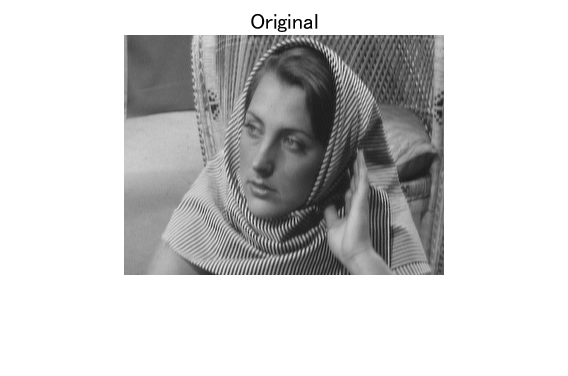

% Original
figure(1)
imshow(u)
title('Original')

間引き画像 (Downsampled)$\{y[\mathbf{m}]\}_\mathbf{m}$

% Downsampled image
figure(2)
subplot(1,2,1)
imshow(y)
title('Downsampled')

ブロック平均画像 (Box-averaged)$\{v[\mathbf{m}]\}_\mathbf{m}$

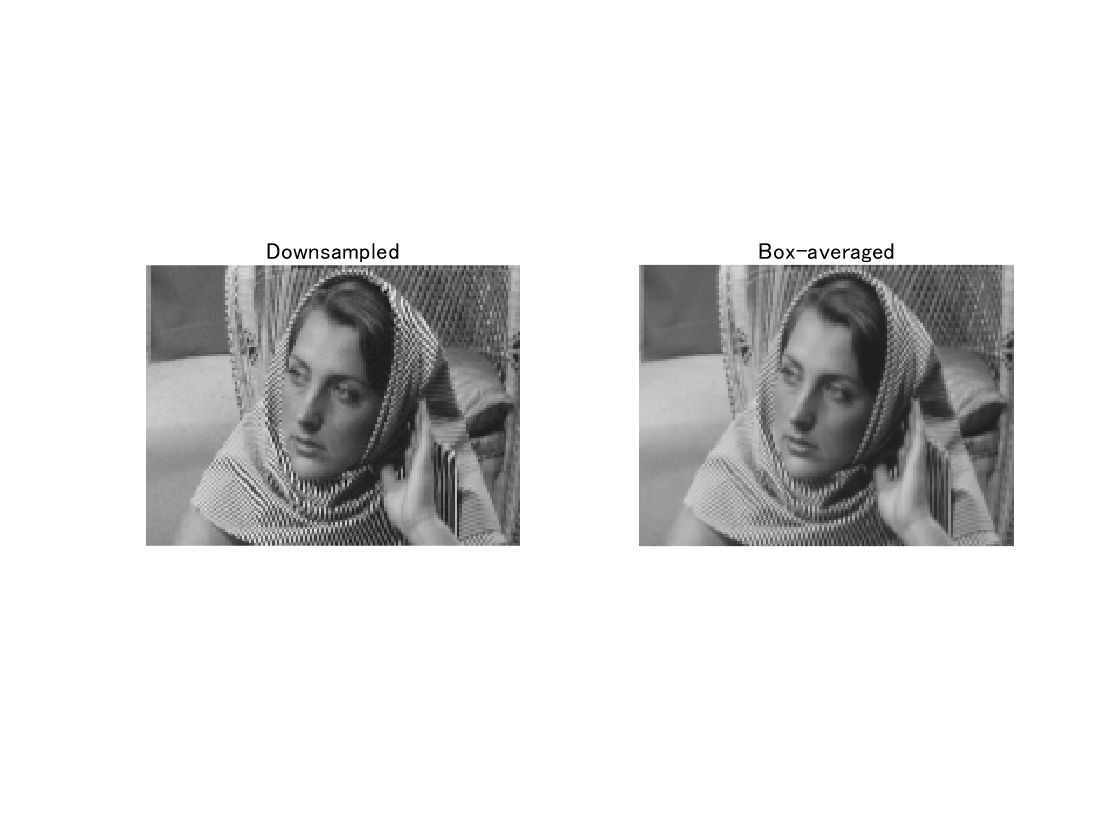

% Box-averaged image
subplot(1,2,2)
imshow(v)
title('Box-averaged')

### 拡大処理

(Size increasing)

零値挿入処理による高解像度化 (Increasing resolution with upsampling)

        
$$y[\mathbf{m}] = \left\{\begin{array}{ll}  u[\mathbf{M}^{-1}\mathbf{m}] & \mathbf{m}\in\mathcal{L}(\mathbf{M}) \\ 0 &\mathrm{otherwise} \\ \end{array}\right.$$


        
$$\mathcal{L}(\mathbf{M})\colon = \{\mathbf{Mk} | \mathbf{k}\in\mathbb{Z}^2\}$$


-  $\{y[\mathbf{m}]\}_\mathbf{m}$: 零値挿入処理の出力画像 (Output image of upsampling)

% Bivariate upsampling function
upsample2 = @(x,n) ...
    shiftdim(upsample(...
    shiftdim(upsample(x,...
    n(1)),1),...
    n(2)),1);

% Upsampling
y = upsample2(u,[verticalFactor horizontalFactor]);

最近傍補間による高解像度化 (Increasing resolution with nearest-neighboring)

        
$$y[\mathbf{m}] = v\left[\lfloor\mathbf{M}^{-1}\mathbf{m}\rfloor\right]$$


-   $\{v[\mathbf{m}]\}_\mathbf{m}$: ブロック平均処理の出力画像 (Output image of nearest-neighboring)

% Box-averaging
sizeNew = size(u).*[verticalFactor horizontalFactor];
v = imresize(u,sizeNew,'nearest');

### 画像の表示

(Display images)

零値挿入画像 (Upsampled)$\{y[\mathbf{m}]\}_\mathbf{m}$

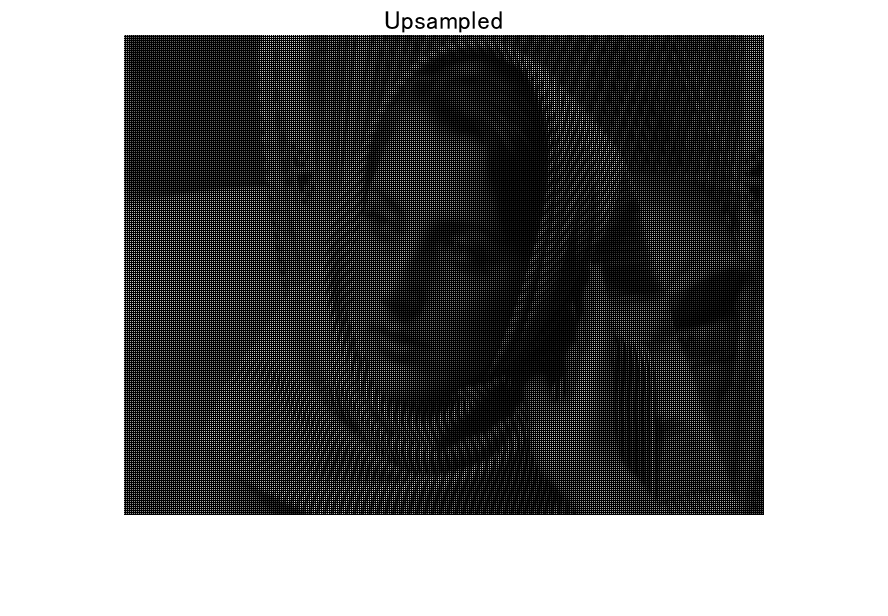

figure(3)
imshow(y)
title('Upsampled')

最近傍補間画像 (Nearest-neigbored)$\{v[\mathbf{m}]\}_\mathbf{m}$

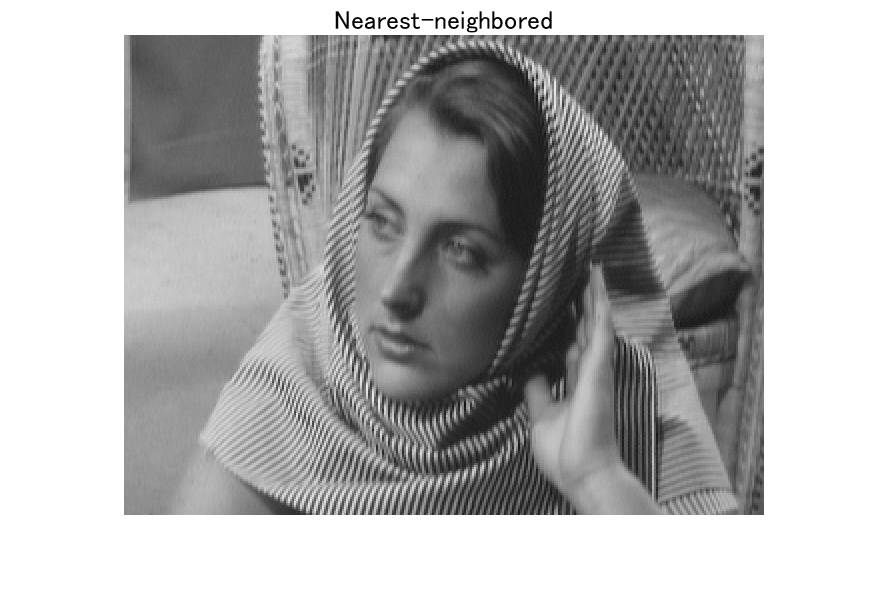

figure(4)
imshow(v)
title('Nearest-neighbored')

© Copyright, Shogo MURAMATSU, All rights reserved.